# Demo:  Simulating 802.11-Like MCS Selection

We first look at MCS selection.  Suppose that a channel has fading with three paths with the following parameters.  For now, we ignore the delays of the paths since we will assume it is not frequency selective.

snrAvg = 15;          % Average SNR in dB
gain = [0, -3, -5]';  % Relative path gains in dB
fd = [0, 10, 7]';     % Doppler shift in Hz

% Random initial phases
npaths = length(gain);
phaseInit = 2*pi*rand(npaths,1);


Suppose we transmit a packet every period of 1ms (`tstep=1e-3) for nt=1000` steps.  We can plot the time evolution of a random realization of the channel as follows.

We can then generate a typical trajectory:

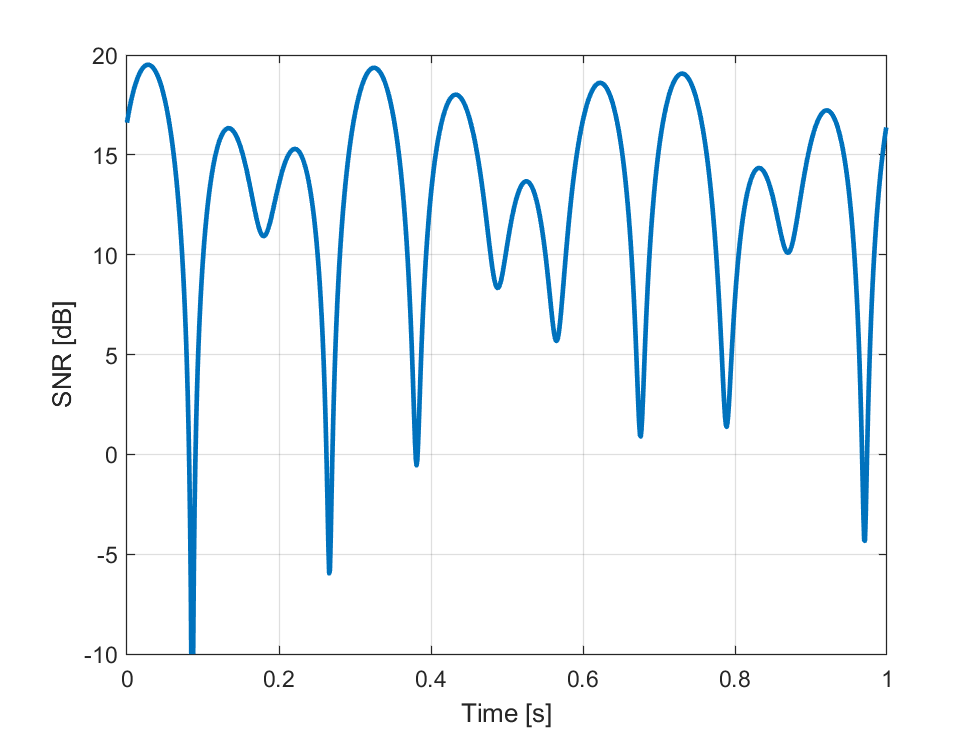

% Convert gains to magnitude and normalize to unit average total power
gainLin = db2mag(gain);
gainLin = gainLin / norm(gainLin);

% Compute times
tstep = 1e-3;
nt = 1e3;
t = (0:nt-1)'*tstep;

% Compute the narrowband response
h = gainLin'.*exp(1i*2*pi*t*fd' + 1i*phaseInit');

% Compute the fading gain in dB and add it to the average SNR
fade = 10*log10( abs(sum(h,2)).^2 );
snr = snrAvg + fade;

% Plot the SNR over time
clf;
plot(t,snr, 'LineWidth',2);
xlabel('Time [s]');
ylabel('SNR [dB]');
ylim([-10,20]);
grid on;

Now suppose the system supports WiFi-like rates as follows:

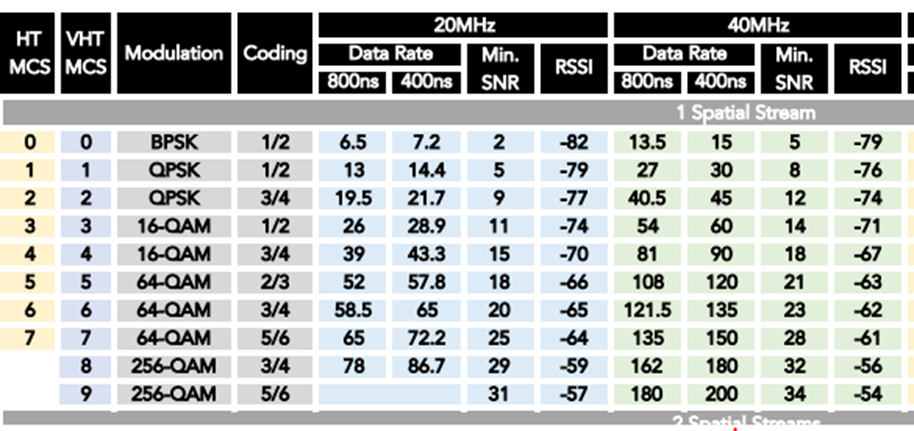

nsc = 52;           % number of data subcarriers
tsym = 4e-6;        % OFDM symbol time (using 800ns GI)

% Code rate, modulation rate, minimum SNR and data rate for each of the MCSs
codeRate = [1/2, 1/2, 3/4, 1/2, 3/4, 2/3, 3/4, 5/6]';
modRate = [1,2,2,4,4,6,6,6]';
minSnr = [2,5,9,11,15,18,20,25]';
rate = codeRate.*modRate*nsc/tsym;

We can find the optimal MCS for each time `k` by finding the highest MCS index `j` such that the SNR at that time is greater than the minimum SNR for that MCS.  Mathematically, this is given as follows:

We can compute this in MATLAB as:

[rateMax, mcsOpt] = max((snr > minSnr').*rate', [], 2);


We can also plot the rate over time along with the SNR.

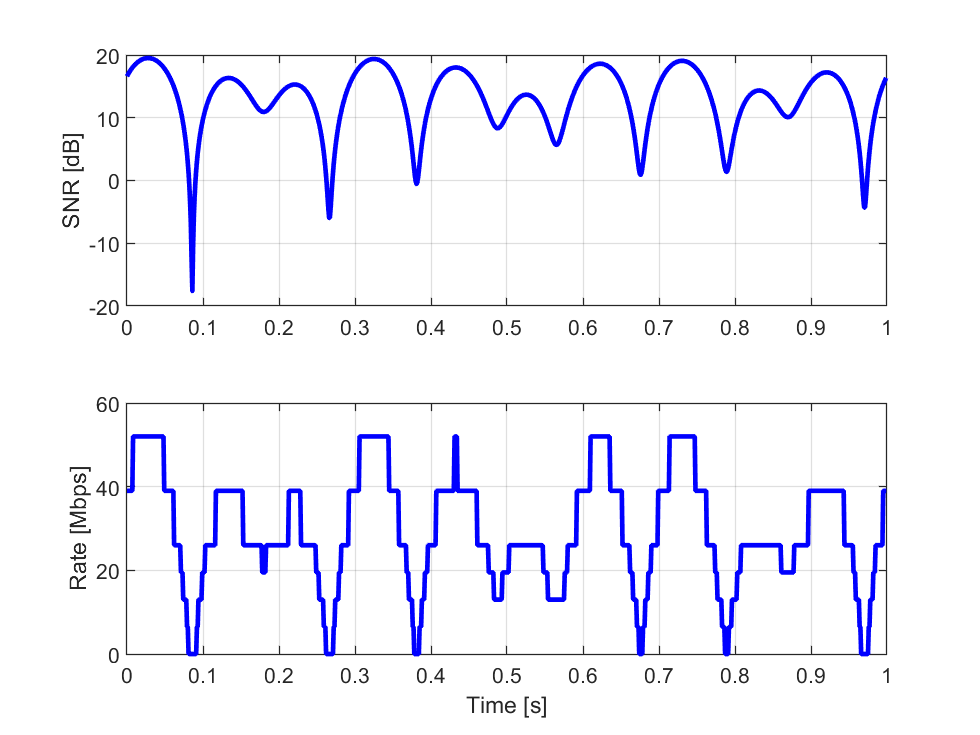

clf;
subplot(2,1,1);
plot(t,snr,'b-', 'LineWidth',2);
grid on;
ylabel('SNR [dB]');
subplot(2,1,2);
plot(t,rateMax/1e6,'b-','LineWidth', 2);
ylabel('Rate [Mbps]');
xlabel('Time [s]');
grid on;

## In-Class Problem

We will now try to implement a trial-and-error:  Let `mcsInd(k)` be the MCS index attempted in time slot `k` and let `rateAdapt(k)` be the goodput in time slot `k`.   We will adapt this MCS index as follows:

- Start with an initial MCS, `mcsInd(1)=1`.

- At each time `k`, check if `snr(k) >= minSnr(mcsInd(k))`, to see if the packet at time `k` passes.

- If the packet fails, set `rateAdapt(k)=0` since no data was transmitted.  Also, decrement the MCS index for the next slot.

- If the packet passes, set `rateAdapt(k) `based on the rate achieved in that time slot.  Also, with probability `pu`p try increase the MCS index for the next slot.

Plot the `rateAdapt `vs.  time. 

% TODO
pup = 0.3;
rateAdapt = zeros(nt,1);
mcsInd = zeros(nt+1,1);
for k = 1:nt

    if snr(k) >= minSnr(mcsInd(k))
        

    end


end


The previous data rate is difficult to visualize.  Filter the rate, `rateAdapt, `with a moving average of `filLen=10 `time steps.  Plot the smoothed rate and the maximum rate vs. time.

clf;
filLen = 10;

% TODO